# Surfaces defined implicitly by functions

A surface in three dimensions can also be implicitly defined by a function of three variables, $f(x,y,z)=0$. For example, the set of points (x,y,z) that satisfy the following equation


$$x^2 + y^2 + z^2 - 1 = 0$$


defines a sphere of radius 1, centered at the origin. A surface defined implicitly can be visualized using **isosurface** in Matlab. First, we will define a mesh in 3D 

x = linspace(-2,2,50)

x =    -2.0000   -1.9184   -1.8367   -1.7551   -1.6735   -1.5918   -1.5102   -1.4286   -1.3469   -1.2653   -1.1837   -1.1020   -1.0204   -0.9388   -0.8571   -0.7755   -0.6939   -0.6122   -0.5306   -0.4490   -0.3673   -0.2857   -0.2041   -0.1224   -0.0408    0.0408    0.1224    0.2041    0.2857    0.3673    0.4490    0.5306    0.6122    0.6939    0.7755    0.8571    0.9388    1.0204    1.1020    1.1837    1.2653    1.3469    1.4286    1.5102    1.5918    1.6735    1.7551    1.8367    1.9184    2.0000


y = linspace(-2,2,50)

y =    -2.0000   -1.9184   -1.8367   -1.7551   -1.6735   -1.5918   -1.5102   -1.4286   -1.3469   -1.2653   -1.1837   -1.1020   -1.0204   -0.9388   -0.8571   -0.7755   -0.6939   -0.6122   -0.5306   -0.4490   -0.3673   -0.2857   -0.2041   -0.1224   -0.0408    0.0408    0.1224    0.2041    0.2857    0.3673    0.4490    0.5306    0.6122    0.6939    0.7755    0.8571    0.9388    1.0204    1.1020    1.1837    1.2653    1.3469    1.4286    1.5102    1.5918    1.6735    1.7551    1.8367    1.9184    2.0000


z = linspace(-5,5,50)

z =    -5.0000   -4.7959   -4.5918   -4.3878   -4.1837   -3.9796   -3.7755   -3.5714   -3.3673   -3.1633   -2.9592   -2.7551   -2.5510   -2.3469   -2.1429   -1.9388   -1.7347   -1.5306   -1.3265   -1.1224   -0.9184   -0.7143   -0.5102   -0.3061   -0.1020    0.1020    0.3061    0.5102    0.7143    0.9184    1.1224    1.3265    1.5306    1.7347    1.9388    2.1429    2.3469    2.5510    2.7551    2.9592    3.1633    3.3673    3.5714    3.7755    3.9796    4.1837    4.3878    4.5918    4.7959    5.0000


[X,Y,Z] = meshgrid(x,y,z)

X = 
(:,:,1) =

   -2.0000   -1.9184   -1.8367   -1.7551   -1.6735   -1.5918   -1.5102   -1.4286   -1.3469   -1.2653   -1.1837   -1.1020   -1.0204   -0.9388   -0.8571   -0.7755   -0.6939   -0.6122   -0.5306   -0.4490   -0.3673   -0.2857   -0.2041   -0.1224   -0.0408    0.0408    0.1224    0.2041    0.2857    0.3673    0.4490    0.5306    0.6122    0.6939    0.7755    0.8571    0.9388    1.0204    1.1020    1.1837    1.2653    1.3469    1.4286    1.5102    1.5918    1.6735    1.7551    1.8367    1.9184    2.0000
   -2.0000   -1.9184   -1.8367   -1.7551   -1.6735   -1.5918   -1.5102   -1.4286   -1.3469   -1.2653   -1.1837   -1.1020   -1.0204   -0.9388   -0.8571   -0.7755   -0.6939   -0.6122   -0.5306   -0.4490   -0.3673   -0.2857   -0.2041   -0.1224   -0.0408    0.0408    0.1224    0.2041    0.2857    0.3673    0.4490    0.5306    0.6122    0.6939    0.7755    0.8571    0.9388    1.0204    1.1020    1.1837    1.2653    1.3469    1.4286    1.5102    1.5918    1.6735    1.7551    1.8367   

Y = 
(:,:,1) =

   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000   -2.0000
   -1.9184   -1.9184   -1.9184   -1.9184   -1.9184   -1.9184   -1.9184   -1.9184   -1.9184   -1.9184   -1.9184   -1.9184   -1.9184   -1.9184   -1.9184   -1.9184   -1.9184   -1.9184   -1.9184   -1.9184   -1.9184   -1.9184   -1.9184   -1.9184   -1.9184   -1.9184   -1.9184   -1.9184   -1.9184   -1.9184   -1.9184   -1.9184   -1.9184   -1.9184   -1.9184   -1.9184   -1.9184   -1.9184   -1.9184   -1.9184   -1.9184   -1.9184   -1.9184   -1.9184   -1.9184   -1.9184   -1.9184   -1.9184   

Z = 
(:,:,1) =

    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5
    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5
    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5
    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5   

Notice that the call to **meshgrid** returns three matrices, X, Y, and Z, all of which contain 50 x 50 x 50 points. These are the x coordinates, y coordinates, and z coordinates respectively at each point on the mesh. 

We now define a function that computes the value of the function at any mesh point. You will find this function at the end of this script, and we copy it here for clarity

**function res = sphere(x,y,z)**

**    res = x.^2 + y.^2 + z.^2 - 1**

**end**

Notice that we use the **.^** operator since the input arguments to this function can and will be matrices. Now we can call this function and visualize the surface

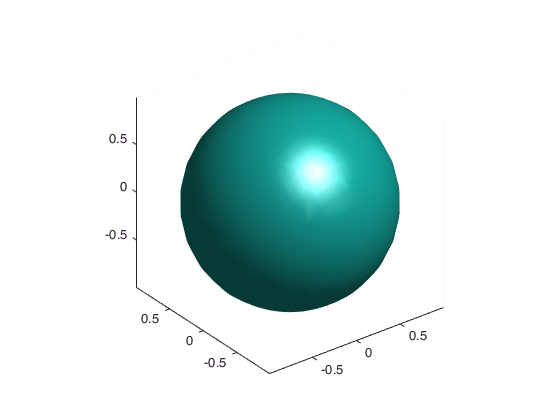

newplot;
V = sphere(X,Y,Z);
isosurface(X,Y,Z,V,0);
view(3);
camlight 
lighting gouraud
axis('equal')

## Generalization

There are lots of implicit surfaces, but a particularly important group is the quadratic (or quadric) surfaces, defined by the equation


$$A x^2 + By^2 + C z^2 + Dyz+Ezx+Fxy+Gx+Hy+Iz+J = 0$$


where A, B, C, D, E, F, G, H, I, and J are all arbitrary constants, some of which may be zero.

**Exercise 1: **Consider the surface defined by the equation $\frac{x^2}{a^2} + \frac{y^2}{b^2} + \frac{z^2}{c^2}-1=0$

- Write a function that accepts x, y, z, a, b, and c as input and returns the value of the expression on the left hand side.

- Visualize the surface for some different values of a, b, and c.

- What features of the surface do a, b, and c control?

**Answer:**

Parameters** a, b** controls the shapes of ellipses on** xy plane**; ** b, c** controls the shapes of ellipses on **yz plane**, while** a, c** controls the shapes of ellipses on** xz plane**. If** a** and** b** and** c** are not equal, the shape would be an **ellipsoid. **If **a = b = c**, it would be a sphere with **radius = a = b = c** (final figure).

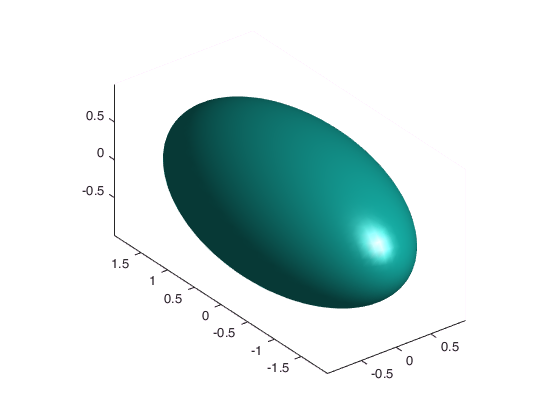

newplot;
V = ellipsoid(X,Y,Z,1,2,1);
isosurface(X,Y,Z,V,0);
view(3);
camlight 
lighting gouraud
axis('equal')

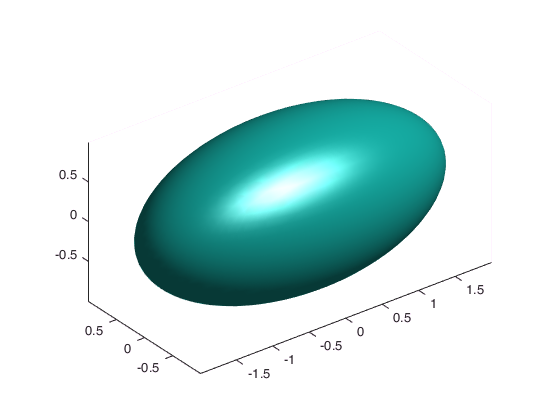

newplot;
V = ellipsoid(X,Y,Z,2,1,1);
isosurface(X,Y,Z,V,0);
view(3);
camlight 
lighting gouraud
axis('equal')

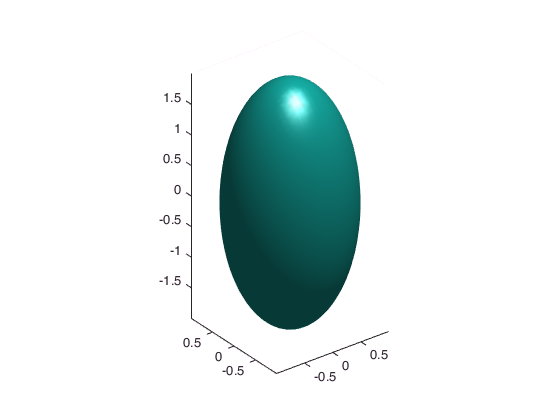

newplot;
V = ellipsoid(X,Y,Z,1,1,2);
isosurface(X,Y,Z,V,0);
view(3);
camlight 
lighting gouraud
axis('equal')

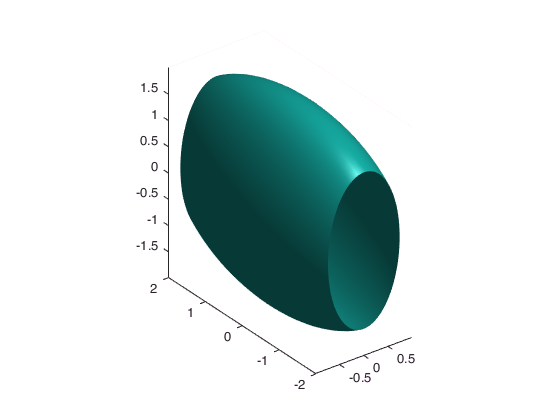

% The shape is cut off
newplot;
V = ellipsoid(X,Y,Z,1,3,2);
isosurface(X,Y,Z,V,0);
view(3);
camlight 
lighting gouraud
axis('equal')

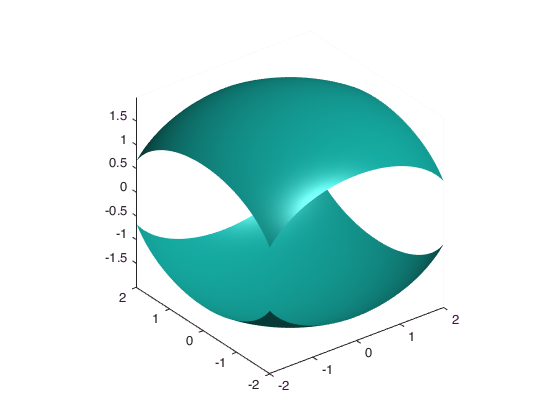

% The shape is cut off
newplot;
V = ellipsoid(X,Y,Z,3,3,2);
isosurface(X,Y,Z,V,0);
view(3);
camlight 
lighting gouraud
axis('equal')

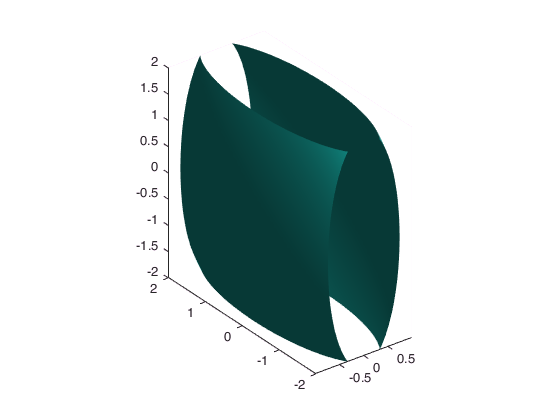

% The shape is cut off
newplot;
V = ellipsoid(X,Y,Z,1,3,3);
isosurface(X,Y,Z,V,0);
view(3);
camlight 
lighting gouraud
axis ('equal')

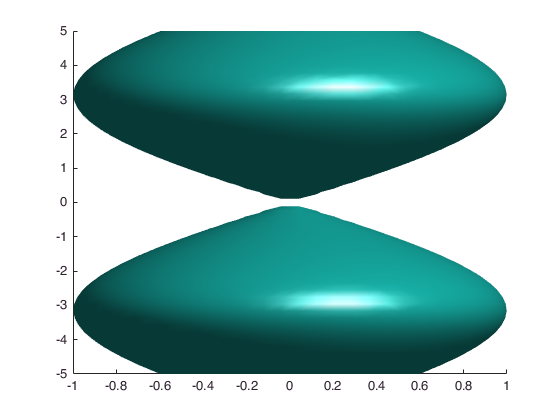

% a = b = c yeild a sphere
newplot;
V = test(X,Y,Z);
isosurface(X,Y,Z,V,0);
view(0,0);
camlight 

lighting gourauds

Error using lighting (line 93)
Lighting methods are none, flat, and gouraud.

axis('equal')


## Function definitions

function res = sphere(x,y,z)
    res = x.^2 + y.^2 + z.^2 - 1;
end

function res = ellipsoid(x,y,z,a,b,c)
    res = x.^2/a.^2 + y.^2/b.^2 + z.^2/c.^2 - 1;
end

function res = test(x,y,z)
    res = x.^2 + y.^2 - (sin(z/2)).^2;
end

